% This script calibrates the two channels (640 and 560) used for imaging DNA
% loci in sequential FISH
% ------------------------------------------------------------------------------------------------------------------------------------------ 
% Input: multidimensional matrices (3D image stacks) of Tetraspeck beads 
% ------------------------------------------------------------------------------------------------------------------------------------------ 
% Output: Warping matrix from the 560 channel to the 640 channel (tform + DeltaZ)
% ------------------------------------------------------------------------------------------------------------------------------------------ 
% Ahilya N. Sawh, PhD
% 23.08.2019
% Version 1.0
% 
% using fitFoci and selectROI functions from the Zhuang lab
%% 
clear all
close all

data = bfopen('251005_1_in_10k_Tetraspeck001.nd2');

Reading series #1
    ........................................................................
    ........................................................................
    ............................................................


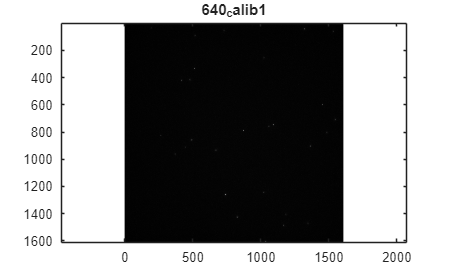

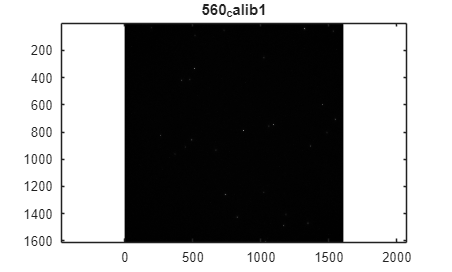

NumSeries = 1;
sz = 1608;

for series = 1:NumSeries
    ImageStack = zeros(sz,sz,204);
    for i = 1:204 %planes are organized by z position first then channel
        ImageStack(:,:,i) = data{series, 1}{i,1};
    end

    %channel 1 = 640
    ImageStack640 = zeros(sz,sz,51);
    ImageStack640 = ImageStack(:,:,1:4:204);
    ImageMax = max(ImageStack640,[],3);
    figure
    imagesc(ImageMax)
    axis equal
    colormap gray
    title(['640_calib' num2str(series)])
    saveas(gcf,['640_calib' num2str(series)])
    save( ['640_calib_' num2str(series) '.mat'],'ImageStack640');

    %channel 2 = 560
    ImageStack560 = zeros(sz,sz,51);
    ImageStack560 = ImageStack(:,:,2:4:204);
    ImageMax = max(ImageStack560,[],3);
    figure
    imagesc(ImageMax)
    axis equal
    colormap gray
    title(['560_calib' num2str(series)])
    saveas(gcf,['560_calib' num2str(series)])
    save( ['560_calib_' num2str(series) '.mat'],'ImageStack560');

end

clear data


%% 
FileName = '640_calib_1.mat';
load(FileName)

for i = 1:size(ImageStack640, 3)
    Std640(i) = std2(ImageStack640(:,:,i)); %calculate the standard deviation of pixel intensity values for the whole slice
end

FileName = '560_calib_1.mat';
load(FileName)

for i = 1:size(ImageStack560, 3)
    Std560(i) = std2(ImageStack560(:,:,i));
end

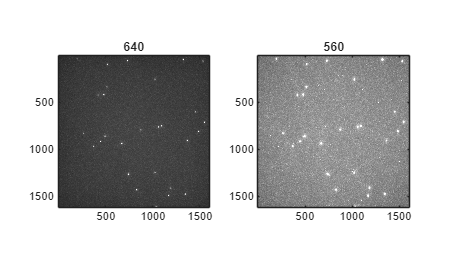


%%

ImageMax640 = max(ImageStack640,[],3);
ImageMax560 = max(ImageStack560,[],3);

figure 
subplot(1,2,1)
imagesc(ImageMax640)
title('640')
colormap gray
axis square
caxis([100 300])
subplot(1,2,2)
imagesc(ImageMax560)
title('560')
colormap gray
axis square
caxis([100 200])

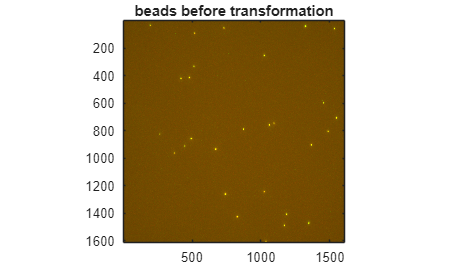


clear RGB
RGB(:,:,1) = ImageMax640/max(max(ImageMax640))*5;
RGB(:,:,2) = ImageMax560/max(max(ImageMax560))*5;
q = size(ImageStack640);
RGB(:,:,3) = zeros(q(1,1),q(1,2));

figure
imagesc(RGB)
axis square
title('beads before transformation')

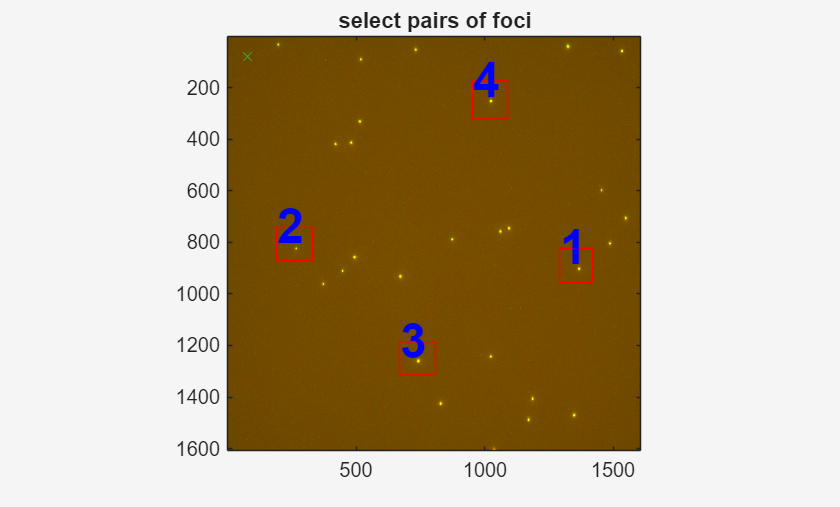

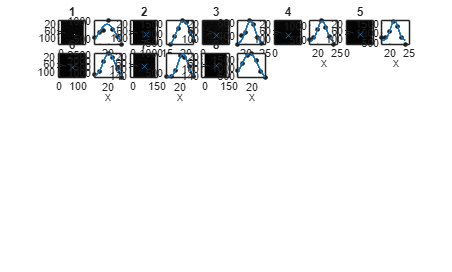


%% align channels in x-y
figure
imagesc(RGB)
axis square
title('select pairs of foci')

WhetherROI = questdlg('Do you want to select ROIs ?');
if(strcmp(WhetherROI, 'Yes'))
    selectROI;
    lmol_match =[];
    rmol_match =[];
for i = 1:length(roiList)
        [Xfit, Yfit, Zfit] = fitFoci(ImageStack640, roiList(i), 2*i-1, 1);
        lmol_match = cat(1, lmol_match, [Xfit, Yfit, Zfit]);
        [Xfit, Yfit, Zfit] = fitFoci(ImageStack560, roiList(i), 2*i, 1);
        rmol_match = cat(1, rmol_match, [Xfit, Yfit, Zfit]);
    end
    tform = cp2tform(rmol_match(:,1:2), lmol_match(:,1:2), 'projective'); 
    save('tform.mat','tform');
end

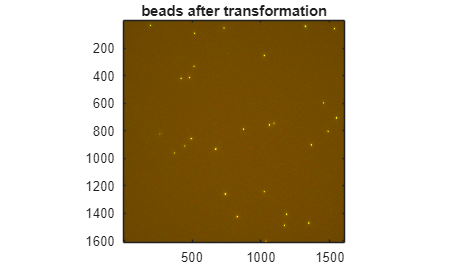


% to use tform
TransImg = imtransform(RGB(:,:,2), tform, 'XData', [1 q(1,1)], 'YData', [1 q(1,1)]);
RGB(:,:,2) = TransImg(1:q(1,1), 1:q(1,1));
figure
imagesc(RGB)
axis square
title('beads after transformation')

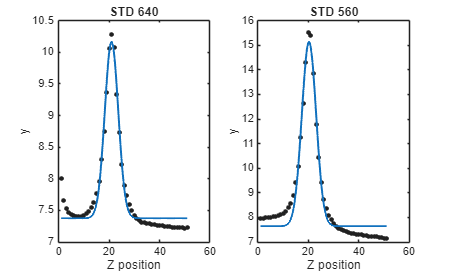


%% align channels in z
GaussEqu = 'a*exp(-(x-b)^2/2/c^2)+d';

StartPoint = [max(Std640) 25 5 0];
f_left = fit([1:length(Std640)]', Std640', GaussEqu, 'Start', StartPoint);

StartPoint = [max(Std560) 25 5 0];
f_right = fit([1:length(Std560)]', Std560', GaussEqu, 'Start', StartPoint);

figure
subplot(1,2,1)
plot(f_left, 1:length(Std640), Std640);
title('STD 640')
xlabel('Z position')
legend('off');
subplot(1,2,2)
plot(f_right, 1:length(Std560), Std560);
legend('off');
title('STD 560')
xlabel('Z position')


DeltaZ = f_right.b - f_left.b; 
save('DeltaZ.mat','DeltaZ');
